
clearvars;close all;clc


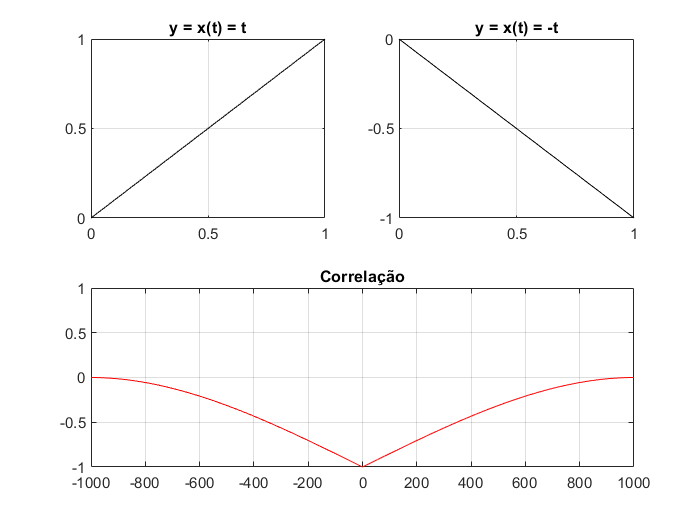


fs = 1000;
t = 0:1/fs:1;
t1 = t;
t2 = -t;
[Rt1t2,lagst] = xcorr(t1,t2,'coeff');
figure;
subplot(221);plot(t,t1,'k');grid on; title('y = x(t) = t')
subplot(222);plot(t,t2,'k');grid on; title('y = x(t) = -t')
subplot(2,2,3:4);plot(lagst,Rt1t2,'r');grid on; title('Correlação')
axis([-1000 1000 -1 1])

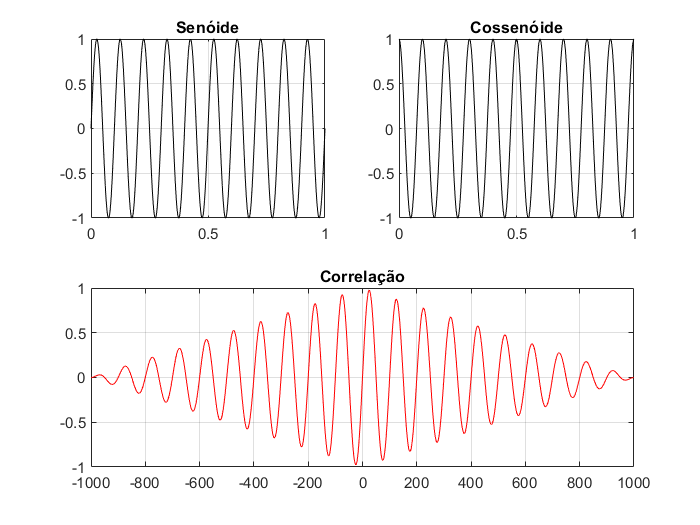



fs = 1000;
t = 0:1/fs:1;
x1 = sin(2*pi*10*t);
x2 = cos(2*pi*10*t);
[Rx1x2,lags] = xcorr(x1,x2,'coeff');
figure;
subplot(221);plot(t,x1,'k');grid on;title('Senóide')
subplot(222);plot(t,x2,'k');grid on;title('Cossenóide')
subplot(2,2,3:4);plot(lags,Rx1x2,'r');grid on; title('Correlação')
axis([-1000 1000 -1 1])

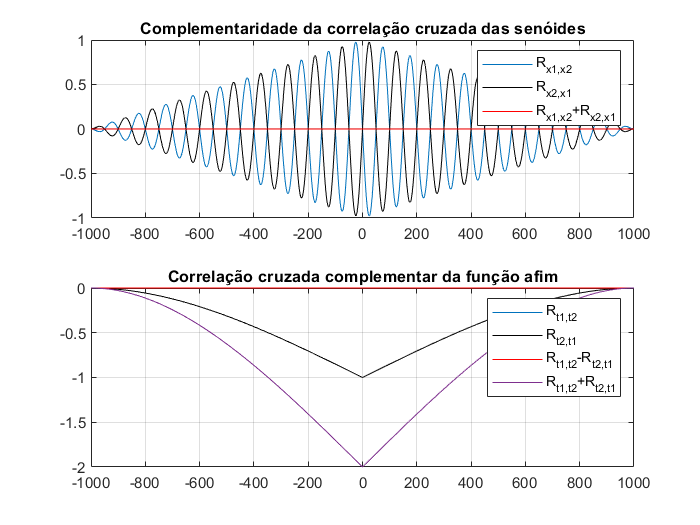


[Rx2x1,lagss] = xcorr(x2,x1,'coeff');
figure;
subplot(211)
plot(lagss,Rx2x1)
hold on
plot(lags,Rx1x2,'k')
plot(lags,round(Rx1x2+Rx2x1),'r')
grid on
legend('R_{x1,x2}','R_{x2,x1}','R_{x1,x2}+R_{x2,x1}')
title('Complementaridade da correlação cruzada das senóides')

[Rt2t1,lagstt] = xcorr(t2,t1,'coeff');
% figure;
subplot(212)
plot(lagstt,Rt2t1)
hold on
plot(lags,Rt1t2,'k')
plot(lags,(Rt1t2-Rt2t1),'r')
plot(lags,(Rt1t2+Rt2t1))
grid on
legend('R_{t1,t2}','R_{t2,t1}','R_{t1,t2}-R_{t2,t1}','R_{t1,t2}+R_{t2,t1}')
title('Correlação cruzada complementar da função afim')

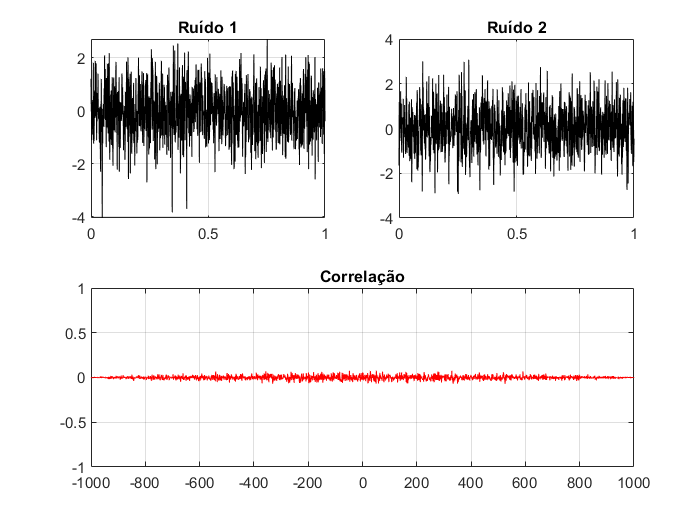



r1 = randn(size(t));
r2 = randn(size(t));
Rr1r2 = xcorr(r1,r2,'coeff');
figure
subplot(221);plot(t,r1,'k');grid on;title('Ruído 1')
subplot(222);plot(t,r2,'k');grid on;title('Ruído 2')
subplot(2,2,3:4);plot(lags,Rr1r2,'r');grid on; title('Correlação')
axis([-1000 1000 -1 1])

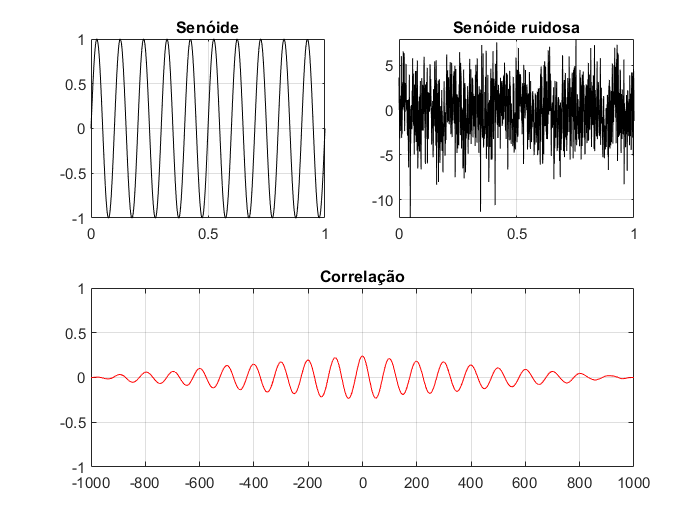


mix = x1 + 3*r1;
Rxx = xcorr(x1,mix,'coeff');
figure
subplot(221);plot(t,x1,'k');grid on;title('Senóide')
subplot(222);plot(t,mix,'k');axis tight;grid on;title('Senóide ruidosa')
subplot(2,2,3:4);plot(lags,Rxx,'r');grid on; title('Correlação')
axis([-1000 1000 -1 1])

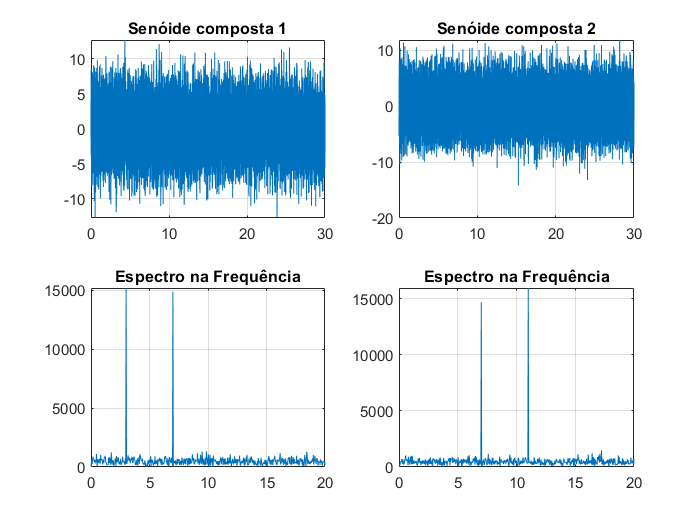



fs = 1024;
t = 0:1/fs:30;
F = linspace(0,fs/2,length(t)/2);
x = sin(2*pi*3*t) + sin(2*pi*7*t) + 3*randn(size(t));
y = sin(2*pi*7*t) + sin(2*pi*11*t) + 3*randn(size(t));
X = abs(fft(x));
Y = abs(fft(y));
figure;
subplot(221);plot(t,x);grid on;title('Senóide composta 1')
subplot(222);plot(t,y);grid on;title('Senóide composta 2')
subplot(223);plot(F,X(1:length(F)));grid on;title('Espectro na Frequência')
axis([0 20 0 max(X)])
subplot(224);plot(F,Y(1:length(F)));grid on;title('Espectro na Frequência')
axis([0 20 0 max(Y)])

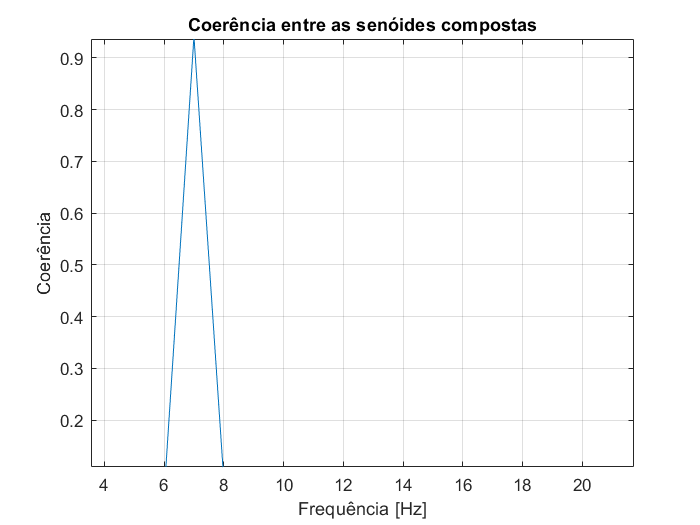


[Cxy,F] = mscohere(x,y,boxcar(1024),0,1024,fs);
figure;plot(F,Cxy)
grid on
title('Coerência entre as senóides compostas')
ylabel('Coerência')
xlabel('Frequência [Hz]')
axis([0 20 0 1])


%%

